# Exploratory Group Assignment

## Mark Belanger, Carter Harris, Meagan Lipsman

### Slide A:

The codes for creating the "sine grate" images (images with stripes) have been provided to you. Use either of those two codes and plot images for 3 different frequencies of sine or cosine waves. Plot the Fourier transforms of the 3 images.

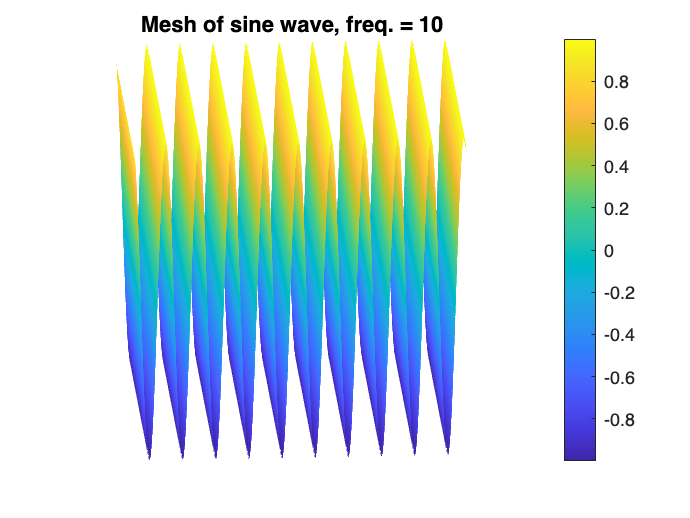

% Create 3D sine mesh
frequency = 10;
phase = 90;
amplitude = 1;
[X,Y]=meshgrid(0:0.001:1,0:0.001:1);
Z = amplitude*sin((2*pi*frequency.*X)+(phase));
surf(X,Y,Z)
title("Mesh of sine wave, freq. = 10")
colorbar
grid on
shading interp
view(0,90)
% colormap gray
axis off
axis square 
view([-3.32 17.45])

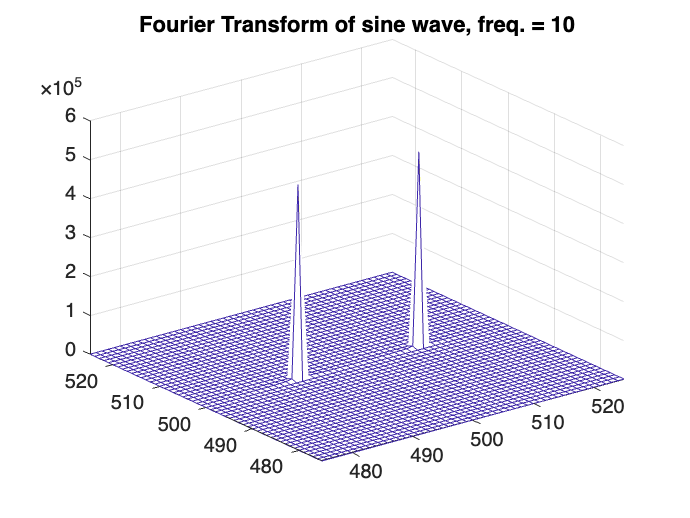


% Fourier Transform
XX=fft2(Z);
figure();
mesh(abs(fftshift(XX)));
xlim([475 525])
ylim ([475 525])
title("Fourier Transform of sine wave, freq. = 10")

Frequency = 2

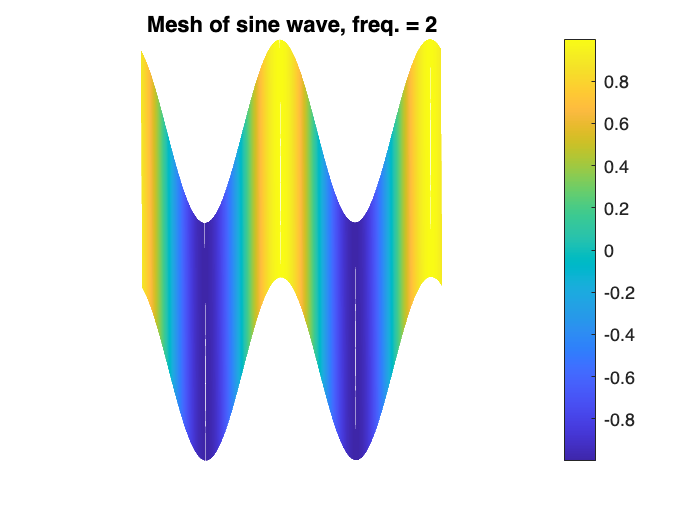

% Create 3D sine mesh
frequency = 2;
phase = 90;
amplitude = 1;
[X,Y]=meshgrid(0:0.001:1,0:0.001:1);
Z = amplitude*sin((2*pi*frequency.*X)+(phase));
surf(X,Y,Z)
title("Mesh of sine wave, freq. = 2")
colorbar
grid on
shading interp
view(0,90)
% colormap gray
axis off
axis square 
view([-0.21 52.46])

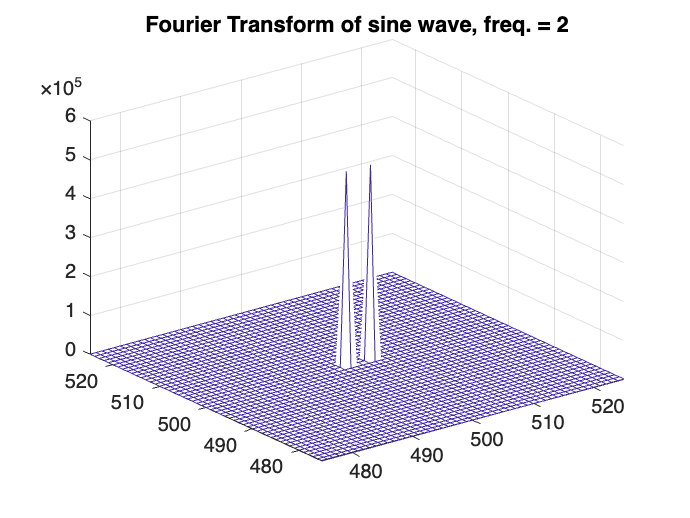


% Fourier Transform
XX=fft2(Z);
figure();
mesh(abs(fftshift(XX)));
xlim([475 525])
ylim([475 525])
title("Fourier Transform of sine wave, freq. = 2")

Frequency = 50

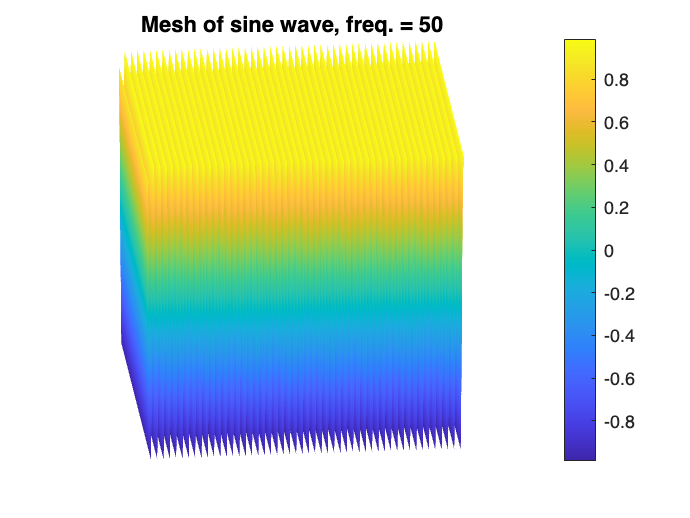

% Create 3D sine mesh
frequency = 50;
phase = 90;
amplitude = 1;
[X,Y]=meshgrid(0:0.001:1,0:0.001:1);
Z = amplitude*sin((2*pi*frequency.*X)+(phase));
surf(X,Y,Z)
title("Mesh of sine wave, freq. = 50")
colorbar
grid on
shading interp
view(0,90)
% colormap gray
axis off
axis square 

view([-5.32 21.53])

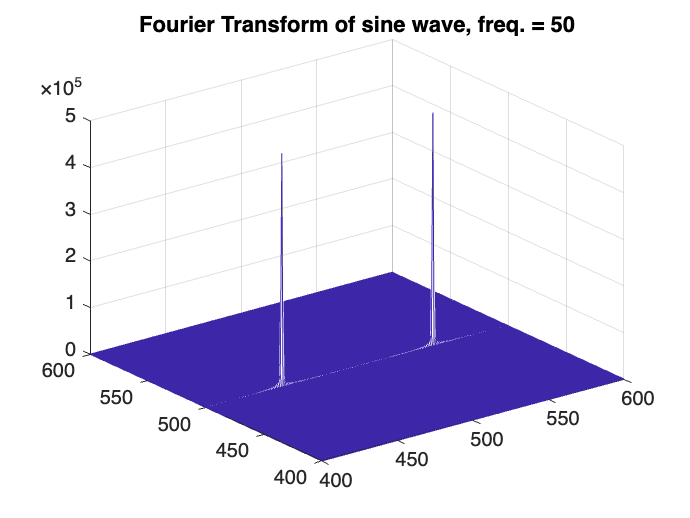


%Fourier Transform
XX=fft2(Z);
figure();
mesh(abs(fftshift(XX)));
xlim([400 600])
ylim([400 600])
title("Fourier Transform of sine wave, freq. = 50")

### Slide B

Create these three shapes in MATLAB or Python, find their Fourier transforms, and verify whether the Fourier transforms shown on the right are correct

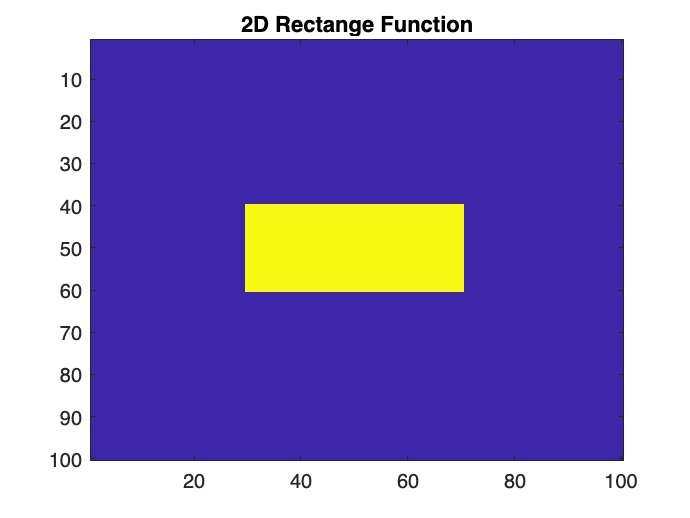

% Create rectangle

Z_rect = zeros(100, 100);
Z_rect(40:60, 30:70) = 1;
imagesc(Z_rect)
title("2D Rectange Function")

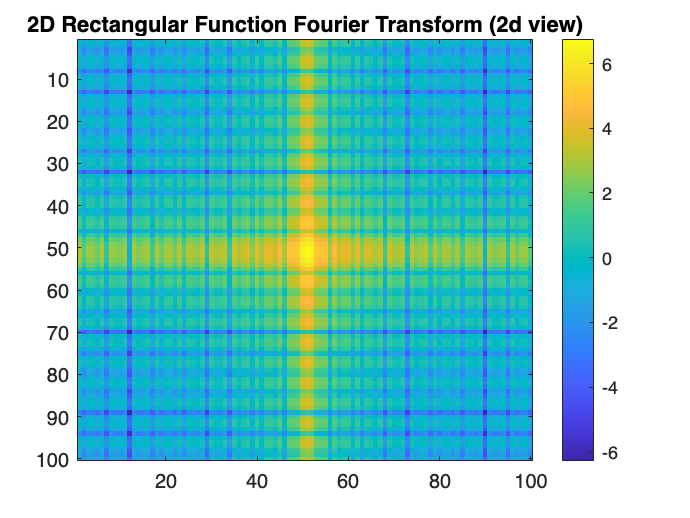


rect_fourier = fft2(Z_rect);
figure();
imagesc(log(abs(fftshift(rect_fourier))))
colorbar
title("2D Rectangular Function Fourier Transform (2d view)")

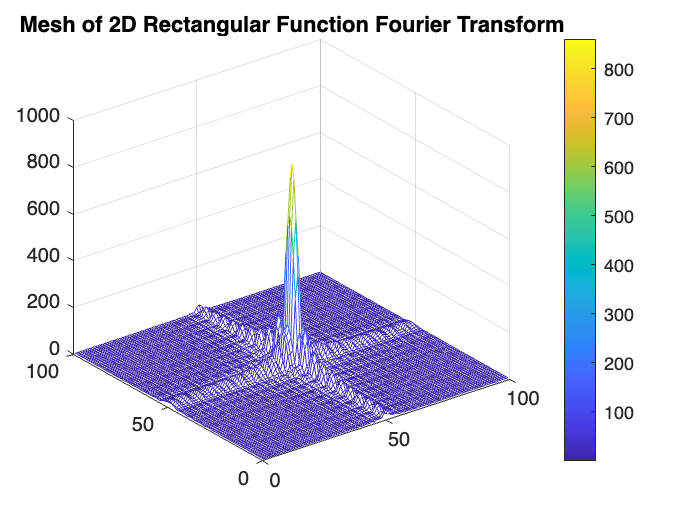

% xlim([25, 75])
% ylim([25, 75])
ftrect = abs(fftshift(rect_fourier));
mesh(ftrect)
colorbar
title("Mesh of 2D Rectangular Function Fourier Transform")

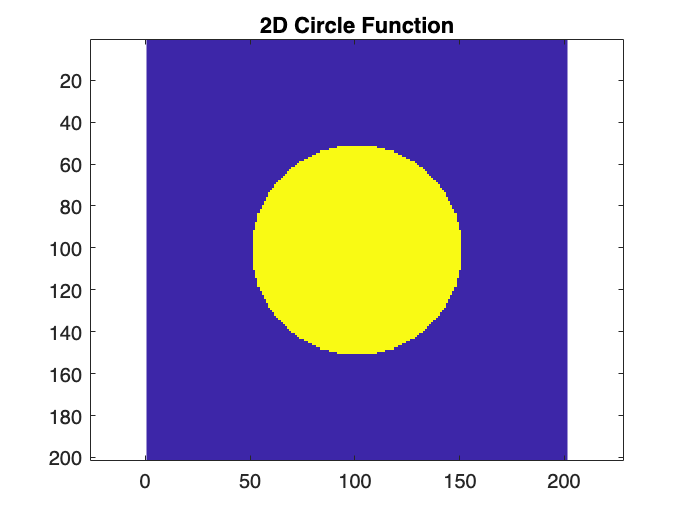

[xx yy] = meshgrid(-100:100, -100:100);
Z_circ = zeros(size(xx));
Z_circ((xx.^2+yy.^2)<50^2) = 1;
imagesc(Z_circ)
axis equal
title("2D Circle Function")

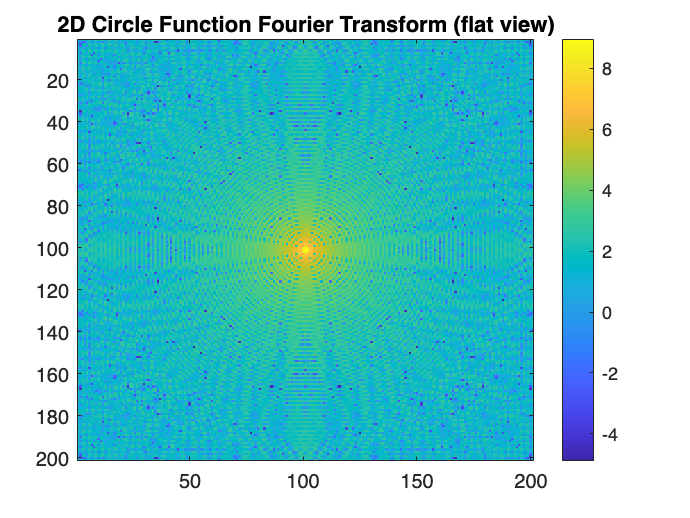


circ_fourier = fft2(Z_circ);
figure();
ftcirc = abs(fftshift(circ_fourier));
imagesc(log(ftcirc))
colorbar
title("2D Circle Function Fourier Transform (flat view)")

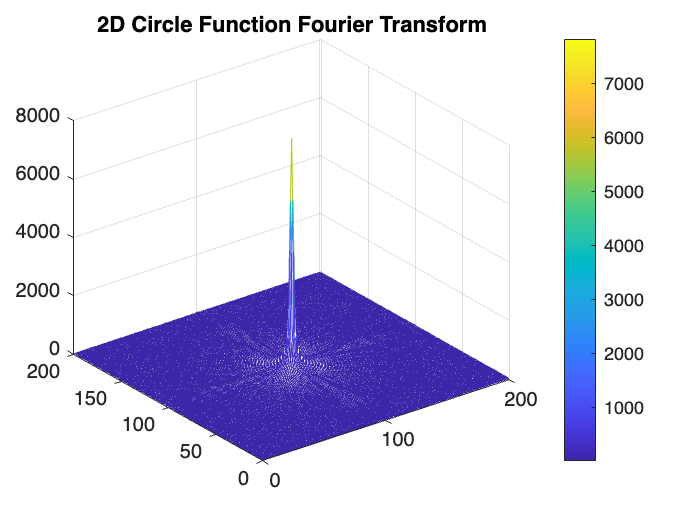

% xlim([25, 75])
% ylim([25, 75])
mesh((ftcirc))
colorbar
title("2D Circle Function Fourier Transform")

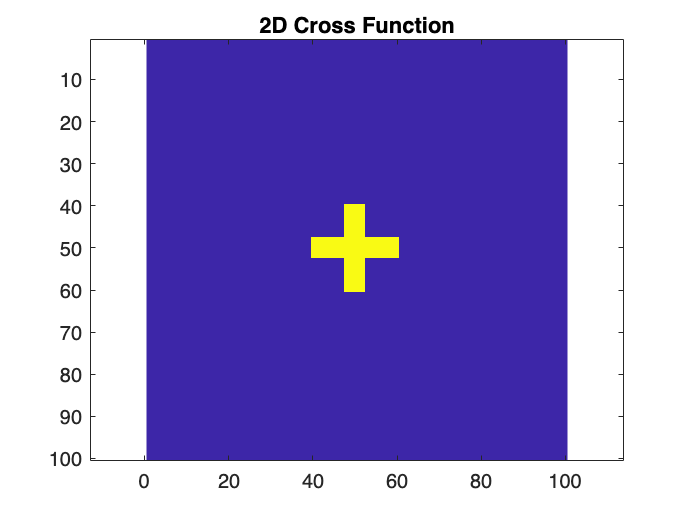

Z_plus = zeros(100, 100);
Z_plus(48:52, 40:60) = 1;
Z_plus(40:60, 48:52) = 1;

imagesc(Z_plus)
axis equal
title("2D Cross Function")

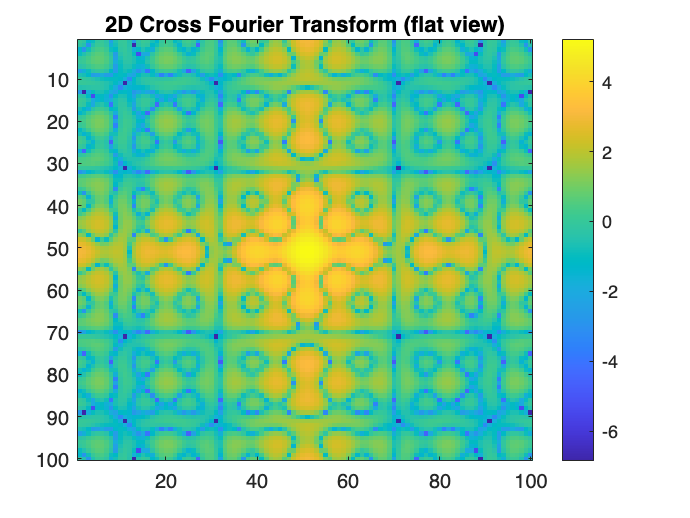


x_fourier = fft2(Z_plus);
figure();
ftx = abs(fftshift(x_fourier));
imagesc(log(ftx))
title("2D Cross Fourier Transform (flat view)")
colorbar

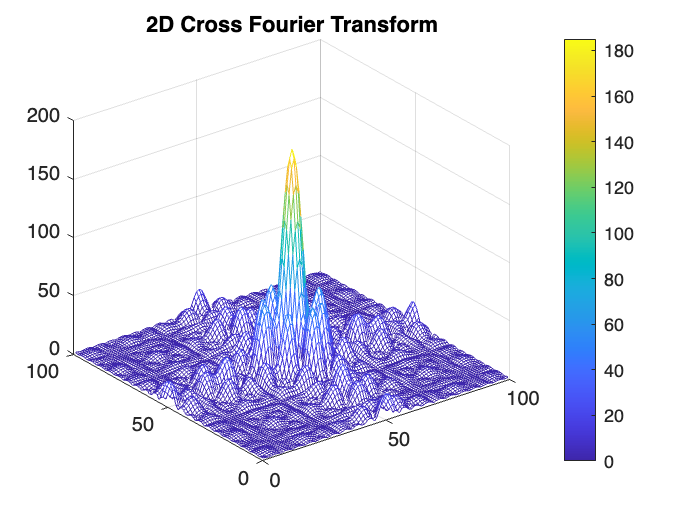

% xlim([25, 75])
% ylim([25, 75])
mesh(ftx)
title("2D Cross Fourier Transform")
colorbar

### Slide C

3) Use an image of your choice, plot its Fourier transform. Comment on whether interpreting the Fourier Transform was intuitive. 

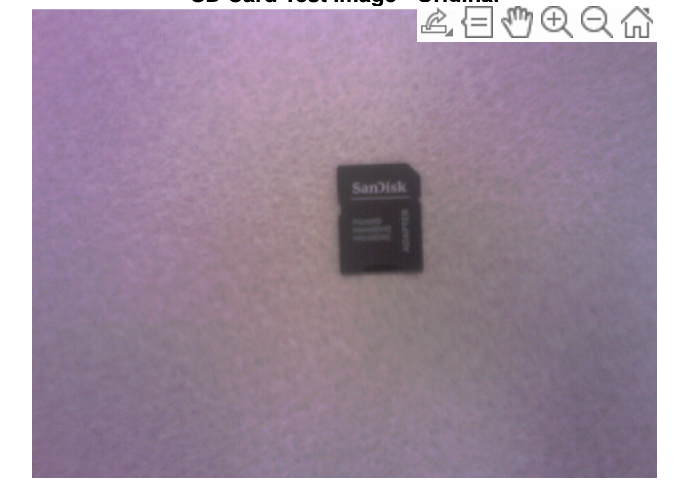

sd = imread("high res.jpg");
imshow(sd)
title("SD Card Test Image - Original")

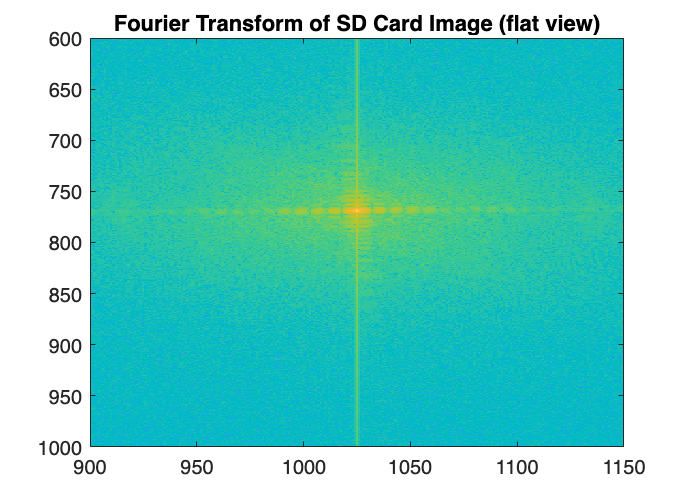


sd_gray = im2gray(sd);
sd_fft = fft2(sd_gray);

Y3 = log(abs(fftshift(sd_fft)));
imagesc(Y3);
xlim([900, 1150])
ylim([600 1000])
title("Fourier Transform of SD Card Image (flat view)")

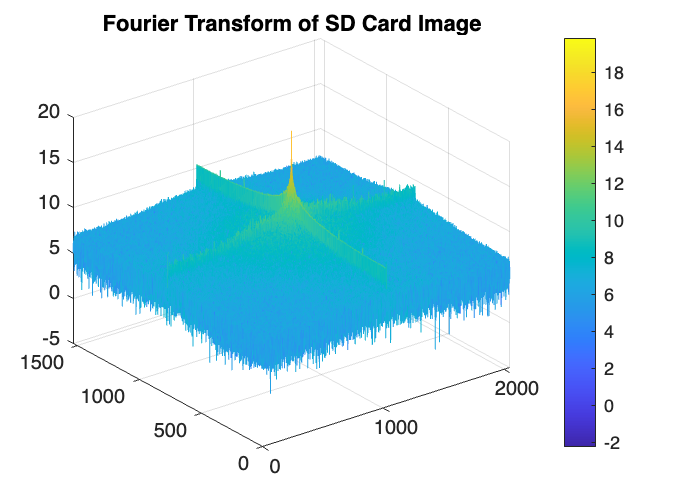


mesh(Y3)
colorbar
title("Fourier Transform of SD Card Image")

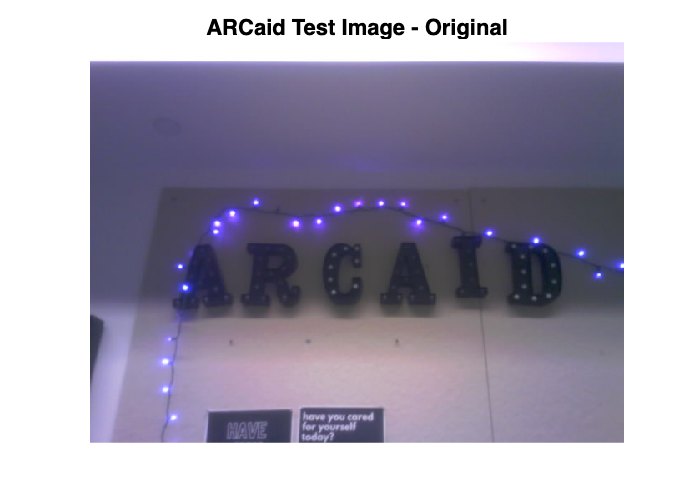

arc = imread("ARCAid.jpg");
imshow(arc)
title("ARCaid Test Image - Original")

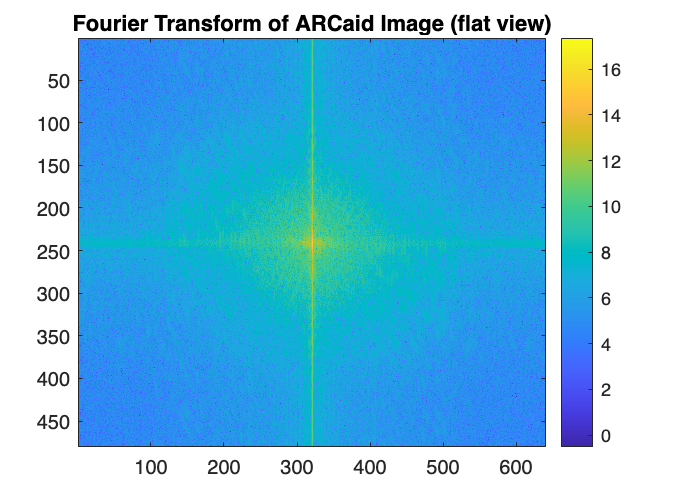


arc_gray = im2gray(arc);
arc_fft = fft2(arc_gray);

Y3 = log(abs(fftshift(arc_fft)));
imagesc(Y3);
title("Fourier Transform of ARCaid Image (flat view)")
colorbar

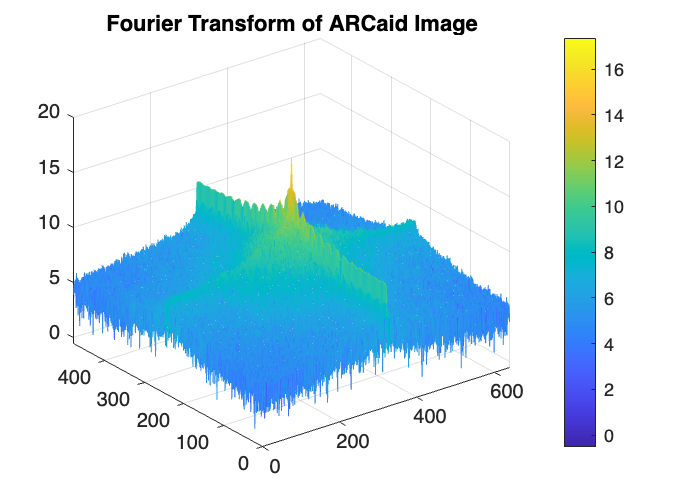


mesh(Y3)
title("Fourier Transform of ARCaid Image")
colorbar

For the SD card image, the FT was very intitute, as it was pretty much the same as the rectangular box we created in Slide B. For the ARCaid image, we were a little more suprised and challaenged when trying to decipher the image. We expected there to be a lot more going on in the FT, as there was much more happening and different objects compared to the SD card, but in reality, there was really just a couple straight lines in the FT. However, there are still lots of straight lines in the image, so this makes sense.